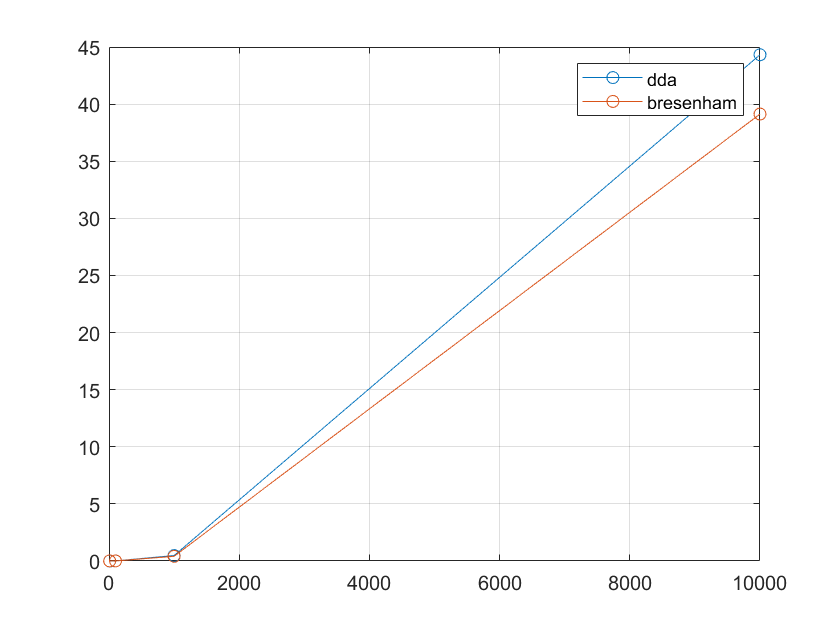

% 绘制时间性能脚本，分别比较绘制10,100,100,10000条直线的时间
times = [10, 100, 1000, 10000];
dda_time = [];
bresenham_time = [];
for time = times
    [t1, t2] = compare(time);
    dda_time = [dda_time, t1];
    bresenham_time = [bresenham_time, t2];
end
plot(times, dda_time, "o-");
hold on;
plot(times, bresenham_time, "o-");
legend("dda", "bresenham");
grid on;